# ALLOCATING RESOURCES AFTER HURRICANE HARVEY EVENTS

## Background and Scope

### Import the Data

StormEvents17 = importproject("StormEvents_2017_finalProject.csv");
StormEvents17;
% Reorder months
monthorder = ["January","February","March","April","May","June","July","August","September","October","November","December"];
StormEvents17.Month = reordercats(StormEvents17.Month,monthorder);
%   Filtering of Data: Affected States
StormEvents17_AffectedStates = StormEvents17(ismember(StormEvents17.State, ...
    {'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
%   Filtering of Data: Within Specified Time Period
StormEvents17_WithinSpecifiedTimePeriod = StormEvents17_AffectedStates(StormEvents17_AffectedStates.End_Date_Time <= '2017-09-03 23:59:01' ...
    & StormEvents17_AffectedStates.Begin_Date_Time >= '2017-08-17 00:00:00',:);
StormEvents17_WithinSpecifiedTimePeriod = sortrows(StormEvents17_WithinSpecifiedTimePeriod,'Begin_Date_Time');
% %   Filtering of Data: Events that Cause Property Damage only
% StormEvents17_WithinSpecifiedTimePeriod = StormEvents17_WithinSpecifiedTimePeriod(~ismissing(StormEvents17_WithinSpecifiedTimePeriod.Property_Cost),:);
% StormEvents17_WithinSpecifiedTimePeriod = StormEvents17_WithinSpecifiedTimePeriod(StormEvents17_WithinSpecifiedTimePeriod.Property_Cost >= 1,:);
%   Filtering of Data: Remove Empty Categories
StormEvents17_WithinSpecifiedTimePeriod.Event_Type = removecats(StormEvents17_WithinSpecifiedTimePeriod.Event_Type);
StormEvents17_WithinSpecifiedTimePeriod.Month = removecats(StormEvents17_WithinSpecifiedTimePeriod.Month);
StormEvents17_WithinSpecifiedTimePeriod.State = removecats(StormEvents17_WithinSpecifiedTimePeriod.State)

StormEvents17_WithinSpecifiedTimePeriod = 573×15 table
    EpisodeID    Event_ID        State         Month        Event_Type         CZ_Name       Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

% writetable(StormEvents17_WithinSpecifiedTimePeriod,"harvey.csv")
% head(StormEvents17_WithinSpecifiedTimePeriod,15);%displays just the first 15 rows

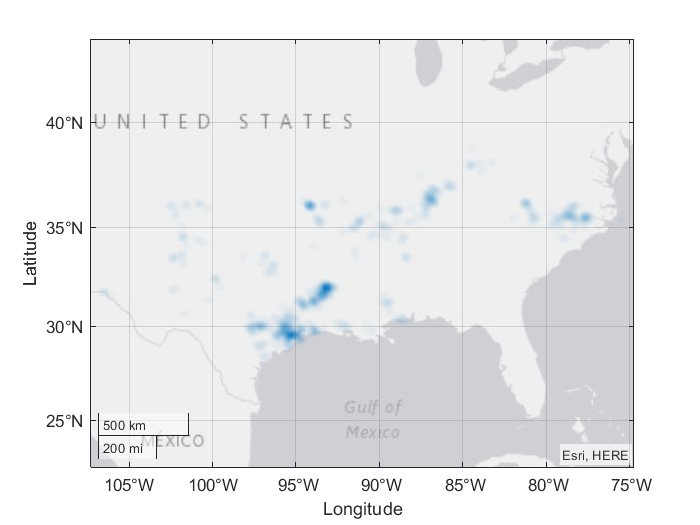

geodensityplot(StormEvents17_WithinSpecifiedTimePeriod.Begin_Lat,StormEvents17_WithinSpecifiedTimePeriod.Begin_Lon);

### Two States Most Impacted by Harvey

The two states most impacted by Hurricane Harvey in terms of total Property Cost are:

- TEXAS

- LOUISIANA

TotalPropertyCostPerState = groupsummary(StormEvents17_WithinSpecifiedTimePeriod,"State","sum","Property_Cost");
TotalPropertyCostPerState = sortrows(TotalPropertyCostPerState,'sum_Property_Cost','descend')

TotalPropertyCostPerState = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                272           77427268000   
    LOUISIANA             85              75277000   
    NORTH CAROLINA        59              12338500   
    MISSISSIPPI           39                915000   
    TENNESSEE             46                504000   
    KENTUCKY              20                435000   
    ARKANSAS              52                 61000   


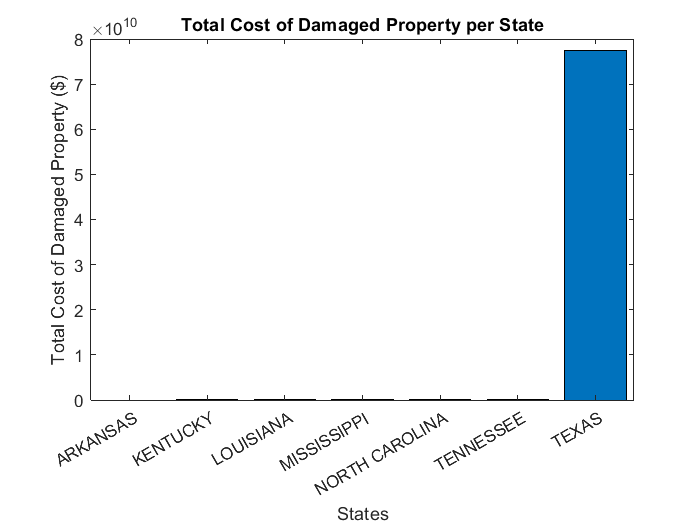

bar(TotalPropertyCostPerState.State,TotalPropertyCostPerState.sum_Property_Cost,'DisplayName','Total Cost of Damaged Property per State');
title('Total Cost of Damaged Property per State');
xlabel('States');
ylabel('Total Cost of Damaged Property ($)');

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

StormEvents17_2MostAffectedStatesOnly = StormEvents17_WithinSpecifiedTimePeriod(ismember(StormEvents17_WithinSpecifiedTimePeriod.State,{'LOUISIANA','TEXAS'}),:)

StormEvents17_2MostAffectedStatesOnly = 357×15 table
    EpisodeID    Event_ID    State    Month        Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

## Visualizations

### Figure of Event Types

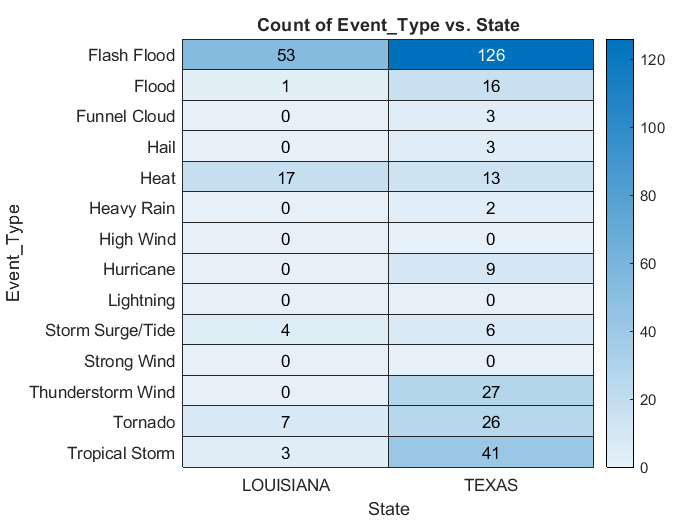

StormEvents17_2MostAffectedStatesOnly.State = removecats(StormEvents17_2MostAffectedStatesOnly.State);
heatmap(StormEvents17_2MostAffectedStatesOnly,"State","Event_Type")

### Figure of Event Locations

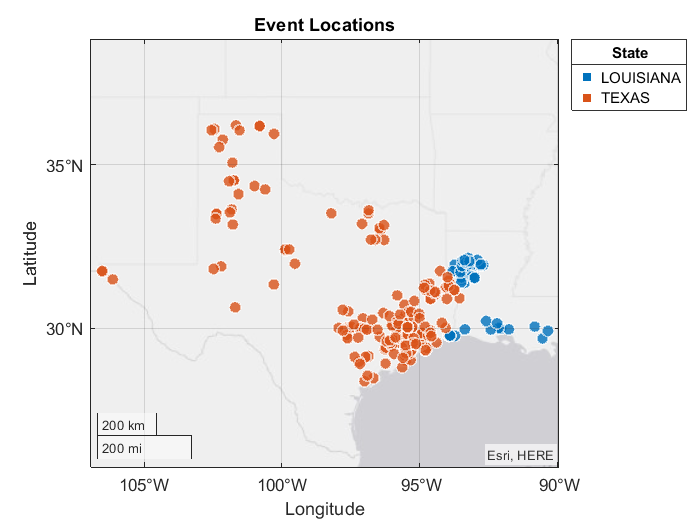

G = geobubble(StormEvents17_2MostAffectedStatesOnly,"Begin_Lat","Begin_Lon","ColorVariable","State","LegendVisible","on");
% geolimits([17.0 55.2],[-128.0 -65.6]);
title(G,"Event Locations");

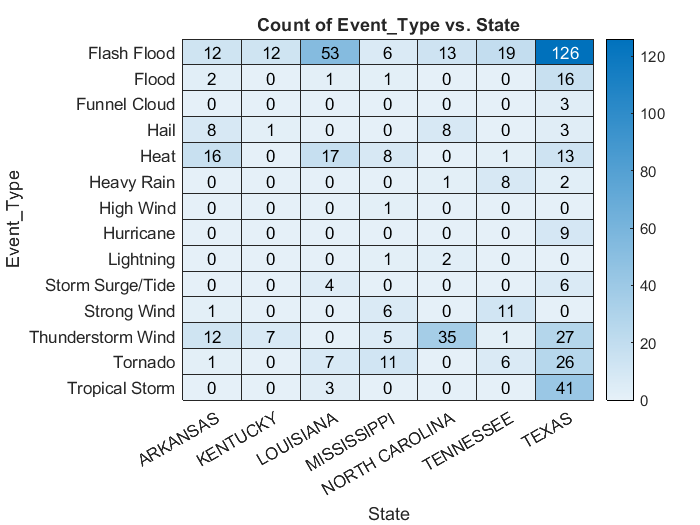

heatmap(StormEvents17_WithinSpecifiedTimePeriod,"State","Event_Type")

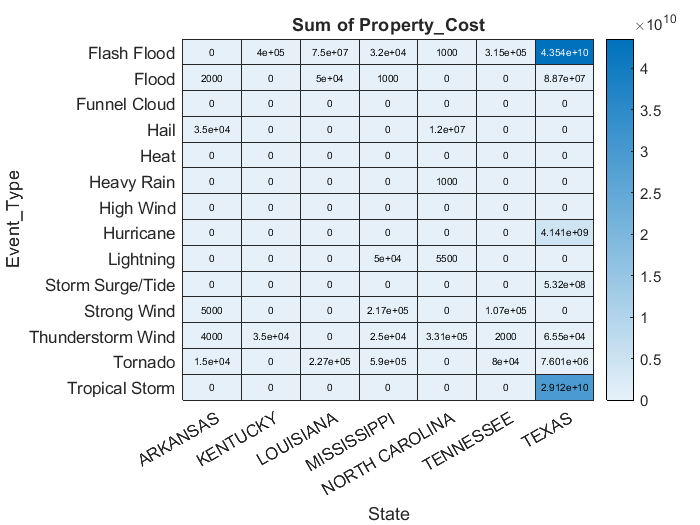

heatmap(StormEvents17_WithinSpecifiedTimePeriod,"State","Event_Type",'ColorVariable','Property_Cost','ColorMethod',"sum")

## Analysis

### Three Counties with Most Events in State 1 (TEXAS)

The three counties with the most events in Texas are:

- HARRIS

- GALVESTON

- FORT BEND

StormEvents17_Texas = StormEvents17_2MostAffectedStatesOnly(StormEvents17_2MostAffectedStatesOnly.State == 'TEXAS',:);
StormEvents17_Texas.CZ_Name = removecats(StormEvents17_Texas.CZ_Name);
% histogram(StormEvents17_Texas.CZ_Name);
A=groupsummary(StormEvents17_Texas,"CZ_Name");
A = sortrows(A,'GroupCount','descend');
head(A,15)%displays the first 15 rows

ans = 15×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            21    
    GALVESTON         17    
    FORT BEND         13    
    ANGELINA          12    
    BRAZORIA          12    
    SABINE            12    
    BASTROP            9    
    CHAMBERS           8    
    CALDWELL           7    
    MONTGOMERY         6    
    MATAGORDA          5    
    WHARTON            5    
    CALHOUN            4    
    FAYETTE            4    
    JEFFERSON          4    


### Three Counties with Most Events in State 2 (LOUISIANA)

The three counties with the most events in Louisiana are:

- NATCHITOCHES

- SABINE, 

- RED RIVER

StormEvents17_Louisiana = StormEvents17_2MostAffectedStatesOnly(StormEvents17_2MostAffectedStatesOnly.State ...
    == 'LOUISIANA',:);
StormEvents17_Louisiana.CZ_Name = removecats(StormEvents17_Louisiana.CZ_Name);
% histogram(StormEvents17_Louisiana.CZ_Name);
B=groupsummary(StormEvents17_Louisiana,"CZ_Name");
B = sortrows(B,'GroupCount','descend')

B = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    VERMILION            4    
    CAMERON              3    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


### Three Counties with Highest Property Cost in State 1 (TEXAS)

The three counties with the highest reported property cost in TEXAS are:

- GALVESTON         $    20,000,201,500

- FORT BEND          $    16,004,330,000

- MONTGOMERY    $    14,000,000,000

C = groupsummary(StormEvents17_Texas,"CZ_Name","sum","Property_Cost");
C = sortrows(C,'sum_Property_Cost','descend');
head(C,15)%displays the first 15 rows

ans = 15×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           17           20000201500   
    FORT BEND           13           16004330000   
    MONTGOMERY           6           14000000000   
    HARRIS              21           10000730000   
    JEFFERSON            4            3000000000   
    BRAZORIA            12            2000780000   
    ARANSAS              2            1950000000   
    ORANGE               2            1500000000   
    NUECES               2            1300000000   
    WALKER               4            1200000000   
    LIBERTY              4            1000000000   
    SAN JACINTO          3             700000000   
    HARDIN               1             600000000   
    POLK                 2             600000000   
    SAN PATRICIO         2             502000000

### Three Counties with Highest Property Cost in State 2 (LOUISIANA)

The three counties with the highest reported property cost in LOUISIANA are: 

-  CALCASIEU             $ 60,000,000

- BEAUREGARD         $ 15,000,000

- ACADIA                     $ 200,000

D=groupsummary(StormEvents17_Louisiana,"CZ_Name","sum","Property_Cost");
D = sortrows(D,'sum_Property_Cost','descend')

D = 30×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU           1             60000000     
    BEAUREGARD          1             15000000     
    ACADIA              1               200000     
    CAMERON             3                72000     
    VERMILION           4                 5000     
    BIENVILLE           1                    0     
    BOSSIER             1                    0     
    CADDO               1                    0     
    CALDWELL            1                    0     
    CLAIBORNE           1                    0     
    DE SOTO             3                    0     
    EAST CAMERON        1                    0     
    GRANT               1                    0     
    IBERIA              1                    0     
    JACKSON             1                    0    

## Conclusions and Recommendations

After much analysis, I can deduce that areas in Texas should be given a lot more attention and contractors should be deployed to these areas. 

Priority should however be given to these five (5) Counties in descending order:

- GALVESTON

- FORT BEND

- MONTGOMERY

- HARRIS

- JEFFERSON

It should be noted that this analysis gives precedence to cost of property damages.

Also given here is a link to an ArcGIS Story map created for this purpose.

Storymap Link: [https://arcg.is/0bWfPy](https://arcg.is/0bWfPy)